# AMECH HW7

*Steven Henderson*

***2.***


$$\mu_{\mathrm{eff}} =\frac{1}{4\eta^4 }-\frac{1}{3\eta^3 }+\frac{l^2 }{\eta^2 }$$


% Initialize Variables
z = linspace(0.5, 5, 1000) ; % values for eta
lsq = [1e-3, 1e-1, 1] ; % values for l squared
% Find normalized potentials for each l squared
u_eff_1 = 1 ./ (4*z.^4) - 1 ./ (3*z.^3) + lsq(3) ./ z.^2 ; % normalize potential for lsq = 1
u_eff_01 = 1 ./ (4*z.^4) - 1 ./ (3*z.^3) + lsq(2) ./ z.^2 ; % normalize potential for lsq = 0.1
u_eff_3 = 1 ./ (4*z.^4) - 1 ./ (3*z.^3) + lsq(1) ./ z.^2 ; % normalize potential for lsq = 0.001
% Plot u_eff's for each lsq value
plot(z, u_eff_1)
hold on
plot(z, u_eff_01)
plot(z, u_eff_3)
hold off
set(gca, 'Fontsize', 22)
legend('$l^2 = 1$', '$l^2 = 10^{-1}$', '$l^2 = 10^{-3}$', 'Interpreter', 'Latex')
xlabel('$\eta (\frac{r}{a})$', 'Interpreter', 'latex')
ylabel('$u_{eff}$', 'Interpreter', 'latex')
[minValue01, idx01] = min(u_eff_01) ;
[minValue, idx] = min(u_eff_3) ;
z(idx)

ans = 1

z(idx01)

ans = 1.3829

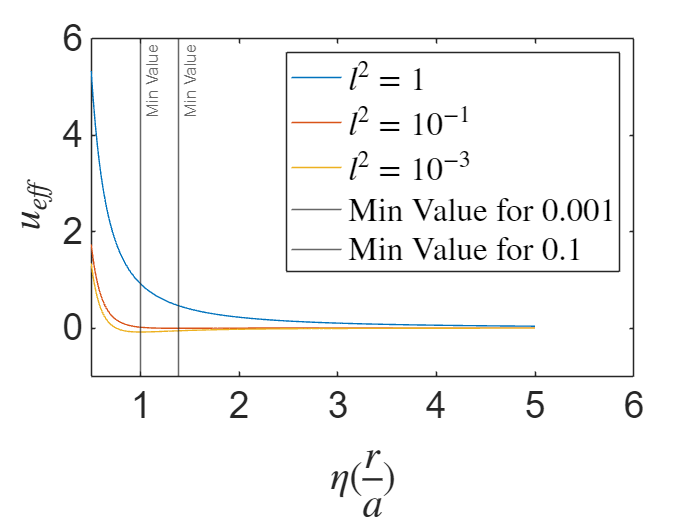

xline(z(idx), 'Label', 'Min Value', 'DisplayName', 'Min Value for 0.001')
xline(z(idx01), 'Label', 'Min Value', 'DisplayName', 'Min Value for 0.1')
xlim([0.5, 6])
ylim([-1, 6])


$$u=\frac{1}{{4\eta }^4 }-\frac{1}{{3\eta }^3 }$$


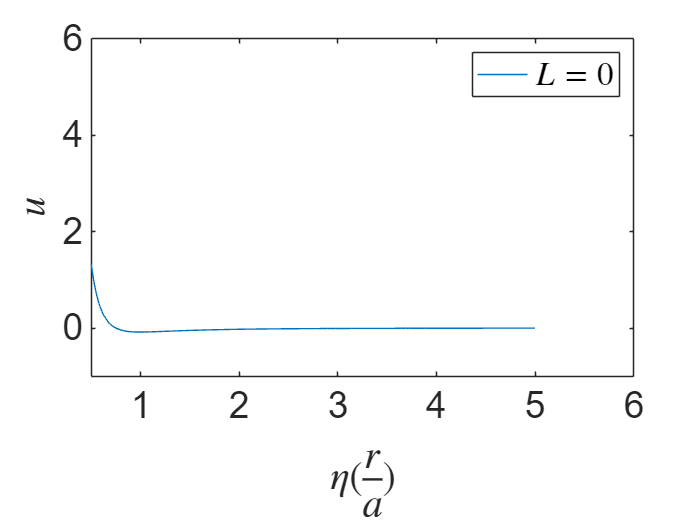

% F) find u using formula above
u = 1 ./ (4*z.^4) - 1 ./ (3*z.^3) ; % normalized potential with L = 0 so l^2 - 0
% Plot results
plot(z, u)
set(gca, 'Fontsize', 22)
legend('$L=0$', 'Interpreter', 'Latex')
xlabel('$\eta (\frac{r}{a})$', 'Interpreter', 'latex')
ylabel('$u$', 'Interpreter', 'latex')
xlim([0.5, 6])
ylim([-1, 6])